# Chemical Reaction - Three Chemical Species

## Task 1 

There are initially 100 molecules of x present, and no molecules of y or z.

Task

The live script to the right is almost complete. Modify it so that it solves the system of ODEs by: 

- defining the time interval `tRange` from 0 to 3,

-  defining the initial condition vector `Y0`, and 

- calling `ode45`, assigning the outputs to `tSol` and `YSol`.

tRange=[0 3]

tRange =      0     3


Y0=[100;0;0]

Y0 =    100
     0
     0


[tSol,YSol]=ode45(@reactionODE,tRange,Y0)

tSol =          0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


YSol =   100.0000         0         0
   99.9999    0.0001    0.0000
   99.9999    0.0001    0.0000
   99.9998    0.0002    0.0000
   99.9998    0.0002    0.0000
   99.9995    0.0005    0.0000
   99.9993    0.0007    0.0000
   99.9990    0.0010    0.0000
   99.9988    0.0012    0.0000
   99.9975    0.0025    0.0000


Do not edit. This code plots the solution.

plot(tSol,YSol(:,1),"r")
hold on
plot(tSol,YSol(:,2),"b")
plot(tSol,YSol(:,3),"m")
hold off

% Annotate plot
legend("chemical x","chemical y","chemical z")
xlabel("time")
ylabel("No. of molecules")

## Further Practice

Take a look at the plot you just created. Did you notice that the amount of y initially increases, then decreases? What's the maximum amount of y present, and at what time does this maximum occur?

One approach is to use `[``val``,``idx``]` `=` `max``(``y``)` to return the maximum of value y

 and its index, then use that index to look up the corresponding time in `tSol`.

y = YSol(:,2);

[ymax,imax] = max(y)

tmax = tSol(imax)

y = YSol(:,2);
[ymax,imax] = max(y)
tmax = tSol(imax)

**ODE function**

Do not edit. This code defines the ODE function for the system of ODEs

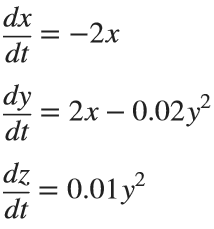

function dYdt = reactionODE(t,Y)
x = Y(1); % chemical x
y = Y(2); % chemical y
z = Y(3); % chemical z
dxdt = -2*x;
dydt = 2*x - 0.02*y^2;
dzdt = 0.01*y^2;
dYdt = [dxdt;dydt;dzdt];
end